
J1 = [-2 0; 0 -2 ] %o

J1 =     -2     0
     0    -2


eig(J1)

ans =     -2
    -2


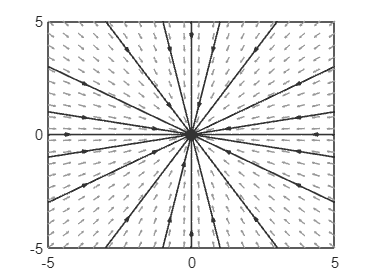

plotpp(@(t, x) J1*[x(1); x(2)])

J1 = [-4 -2; -2 0 ] %x

J1 =     -4    -2
    -2     0


eig(J1)

ans =    -4.8284
    0.8284


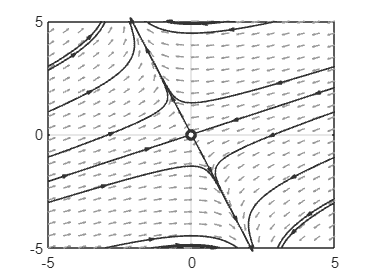

plotpp(@(t, x) J1*[x(1); x(2)])

J1 = [60 0; -30 -60 ] %*

J1 =     60     0
   -30   -60


eig(J1)

ans =    -60
    60


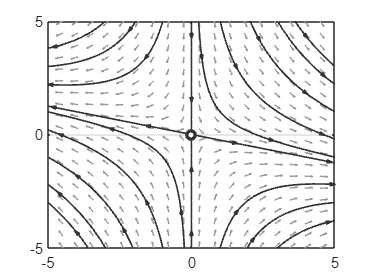

plotpp(@(t, x) J1*[x(1); x(2)])

J1 = [-80 -40; -20 -40 ] %kwadrat

J1 =    -80   -40
   -20   -40


eig(J1)

ans =   -94.6410
  -25.3590


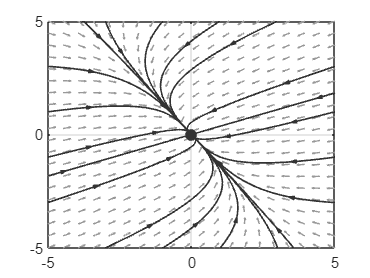

plotpp(@(t, x) J1*[x(1); x(2)])

x0=[-pi/4,0]

x0 =    -0.7854         0


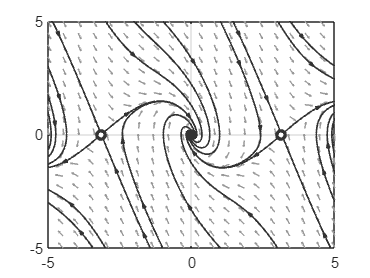

[t,x] = ode45(@(t,x) kolos(t,x), [0, 5], x0);
plotpp(@(t,x)[x(2); - 2*x(2)-10/3*sin(x(1))])

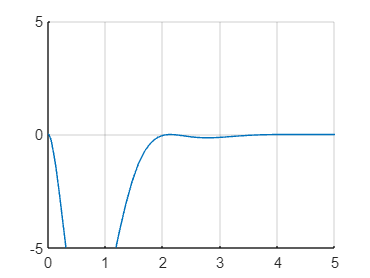

figure
xx=-(9*2)*x(:,2).^2;
hold on
plot(t,xx)
ylim([-5 5])
%plot(t,x(:,1))
grid on
hold off

function dxdt = system33(t,x)
    dxdt = zeros(2,1);
    dxdt(1) = -x(1)^3 - a*x(1) + x(2);
    dxdt(2) = -x(1);
end

function dxdt = kolos(t,x,a)
    dxdt = zeros(2,1);
    dxdt(1) = x(2);
    dxdt(2) = - 2*x(2)-10/3*sin(x(1));
end